# Práctica 7: Ejercicios propuestos

### 1. Problemas de valor inicial

#### a)

% Definir el sistema de ecuaciones de primer orden
f = @(t, y) [3*y(1)-0.002*y(1)*y(2); 0.0006*y(2)-0.5*y(2)];

% Condiciones iniciales
alpha = [1000; 500];  % y(0) = 0, y'(0) = 0

% Intervalo de tiempo
a = 0;
b = 4;
h = 0.1;  % Tamaño del paso (se usa solo para discretización en la salida)

% Llamada a ode45
[t, x] = ode45(f, a:h:b, alpha);

% Mostrar los resultados
disp(table(t, x(:,1), x(:,2), 'VariableNames', {'t', 'y', 'y_prime'}));

     t         y         y_prime
    ___    __________    _______

      0          1000       500 
    0.1        1224.4    475.64 
    0.2        1506.5    452.47 
    0.3        1861.6    430.43 
    0.4        2310.4    409.46 
    0.5        2879.3    389.52 
    0.6        3602.8    370.54 
    0.7        4523.7    352.49 
    0.8        5700.1    335.32 
    0.9        7207.4    318.99 
      1        9143.4    303.45 
    1.1         11632    288.67 
    1.2         14840     274.6 
    1.3         18988    261.23 
    1.4         24362     248.5 
    1.5         31326     236.4 
    1.6         40375    224.88 
    1.7         52165    213.93 
    1.8         67549     203.5 
    1.9         87622    193.59 
      2    1.1388e+05    184.16 
    2.1    1.4831e+05    175.19 
    2.2    1.9351e+05    166.66 
    2.3    2.5282e+05    158.54 
    2.4    3.3083e+05    150.81 
    2.

[t, y1, y2] = rungeKutta(h, 1)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y1 =          0    0.0010    0.0038    0.0083    0.0143    0.0217    0.0303    0.0400    0.0506    0.0620    0.0741


y2 =          0    0.0192    0.0368    0.0528    0.0673    0.0802    0.0917    0.1017    0.1103    0.1176    0.1236




f_exacta = @(t) exp(1).^sin(t);
format short
edosgeneral(f, f_exacta, alpha, a, b, h);

Error using Prtc7>@(x)x+(1./x)
Too many input arguments.

Error in euler (line 10)
        w(:,i+1) = w(:,i) + h * f(t(i), w(:,i));

Error in edosgeneral (line 10)
        [t, w_euler] = euler(f, a, b, alpha, h(i));

#### b)


% Definir el sistema de ecuaciones de primer orden
f = @(t, y) 1/t^2 - y/t -y^2;

% Condiciones iniciales
alpha = -1;  % y(0) = 0, y'(0) = 0

% Intervalo de tiempo
a = 1;
b = 2;
h = 0.1;  % Tamaño del paso (se usa solo para discretización en la salida)
f_exacta = @(t) t ./ (1 + t.^2);

edosgeneral(f, f_exacta, alpha, a, b, h);

Intervalo 1
 
     t     w(Euler)    w(Euler mejorado)    w(Punto medio)    w(ode45)    w_exacta
    ___    ________    _________________    ______________    ________    ________

      1          -1              -1                  -1             -1        0.5 
    1.1        -0.9        -0.90827            -0.90907       -0.90909    0.49774 
    1.2    -0.81654        -0.83187             -0.8333       -0.83333     0.4918 
    1.3    -0.74572        -0.76723            -0.76918       -0.76923    0.48327 
    1.4     -0.6848        -0.71183            -0.71423       -0.71429    0.47297 
    1.5    -0.63176        -0.66381             -0.6666       -0.66667    0.46154 
    1.6    -0.58511        -0.62179            -0.62493         -0.625    0.44944 
    1.7    -0.54371        -0.5846

#### c) Sistema de EDO's

h = 0.2;
alpha = [1 1];
a = 0;
b = 1;
tspan = [a b];
f = @(t,u) [3.*u(1) + 2.*u(2) - (2.*t.^2 +1).*exp(1).^2.*t;
            4*u(1) + u(2) + (t.^2 + 2*t -4).*exp(1)^2*t];

[t_euler, w_euler] = euler(f, a, b, alpha, h);

[t_eulermejorado, w_eulermejorado] = eulermejorado(f, a, b, alpha, h);

[t_puntomedio, w_puntomedio] = puntomedioedo(f, a, b, alpha, h);
w_puntomedio = w_puntomedio';

[t_ode45, w_ode45] = ode45(f, tspan, alpha);
w_ode45 = w_ode45';
t_ode45 = t_ode45';

w_ode45_interpolada = zeros(2,length(t_euler));
aux = length(t_ode45);
cont = 1;
for k = 1:aux
    if abs(t_ode45(k) - t_euler(cont)) < 10^-2
        w_ode45_interpolada(:, cont) = w_ode45(:, k);
        cont = cont + 1;
    end
end

u_exacta = @(t) [(1/3)*exp(5*t) - (1/3)*exp(-t) + exp(2.*t);
               (1/3)*exp(5*t) - (2/3)*exp(-t) + (t.^2).*exp(2.*t)];
u_solucion = u_exacta(t_euler);

num_vars = length(alpha);
col_names = {};
table_data = {};

for i = 1:num_vars
    col_names{end+1} = ['U' num2str(i) ' Euler'];
    col_names{end+1} = ['U' num2str(i) ' Euler mejorado'];
    col_names{end+1} = ['U' num2str(i) ' Punto medio'];
    col_names{end+1} = ['U' num2str(i) ' ode45'];
    col_names{end+1} = ['U' num2str(i) ' exacta'];
    table_data{end+1} = w_euler(i,:)';
    table_data{end+1} = w_eulermejorado(i,:)';
    table_data{end+1} = w_puntomedio(i,:)';
    table_data{end+1} = w_ode45_interpolada(i,:)';
    table_data{end+1} = u_solucion(i,:)';
end

tabla = table(table_data{:}, 'VariableNames', col_names);
disp(tabla);

    U1 Euler    U1 Euler mejorado    U1 Punto medio    U1 ode45    U1 exacta    U2 Euler    U2 Euler mejorado    U2 Punto medio    U2 ode45    U2 exacta
    ________    _________________    ______________    ________    _________    ________    _________________    ______________    ________    _________

          1               1                   1              1           1            1               1                   1              1     -0.33333 
          2          2.3404              2.3493         2.3356       2.125            2          1.9739              1.9399         1.9982      0.41995 
     3.6808          4.7898              4.8146

#### d) Ecuaciones diferenciales de orden superior

%% y'' - 2y' + y = te^t - t
f = @(t, w) [w(2);
            2*w(2) - w(1) + t*exp(t)-t];
tspan = [0 1];
alpha = [0 0];
[t, w] = eulermejorado(f, 0, 1, alpha, 0.1);
t = t';
w = w';
f_exacta = @(t) (1/6).*t.^3.*exp(1)-t.*exp(t)+2.*exp(t)-t-2;
f_sol = f_exacta(t);
tabla = table(t, w(:,1), f_sol, 'VariableNames', {'t', 'aprox.', 'exac.'});
disp(tabla);

     t       aprox.        exac.   
    ___    __________    __________

      0             0             0
    0.1             0    0.00027779
    0.2    0.00011043     0.0021493
    0.3    0.00071452     0.0069922
    0.4     0.0025695      0.015915
    0.5      0.006927      0.029713
    0.6       0.01568      0.048824
    0.7      0.031545      0.073274
    0.8      0.058279       0.10261
    0.9       0.10095       0.13583
      1       0.16624       0.17133



### 2. Problemas de valores en la frontera: disparo lineal

f = @(x, y, yp) yp+2*y+cos(x);
a = 0;
b = pi/2;
alpha = -0.3;
beta = -0.1;
h = pi/8;
[t,w] = disparolineal(f, a, b, alpha, beta, h);
tabla = table(t', w, 'VariableNames', {'t', 'Aprox. Disparo Lineal'});
disp(tabla);

      t       Aprox. Disparo Lineal
    ______    _____________________

         0              -0.3       
    0.3927          -0.31543       
    0.7854          -0.28284       
    1.1781          -0.20719       
    1.5708              -0.1       



### 3. Problemas de valores en la frontera: disparo no lineal

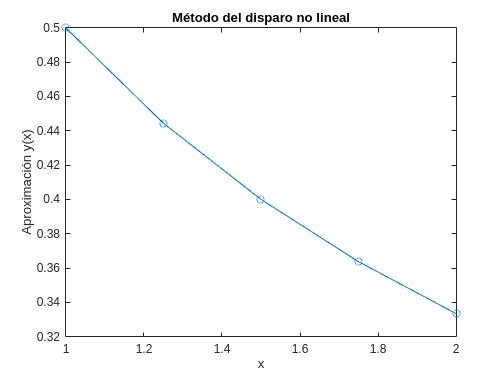

%% Disparo no lineal
f = @(x, y, yp) y^3-y*yp;
a = 1;
b = 2;
alpha = 1/2;
beta = 1/3;
h = 0.25;

[x, w] = disparonolineal(f, a, b, alpha, beta, h);


disp(num2str(w,10))

         0.5
 0.444444929
 0.400000943
0.3636377549
0.3333351785


f = @(x) x+(1./x);
f_solved = f(t);
tabla = array2table([t; w; f_solved], 'VariableNames', compose("N: %d", 1:length(t)), 'RowNames', {'t', 'Aprox. Disparo no lineal w(1)', 'Aprox. Disparo no lineal w(2)', 'Solución exacta'});

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

disp(tabla);
intervalo = [1 2];
alpha = 1/4;
beta = 1/5;
h = 0.25;
f = @(x,w) [w(2); 2*w(1)^3];
[t,w] = disparonolineal(f, intervalo, alpha, beta, h);
f = @(x) x+(1./x);
f_solved = f(t);
tabla = array2table([t; w; f_solved], 'VariableNames', compose("N: %d", 1:length(t)), 'RowNames', {'t', 'Aprox. Disparo no lineal w(1)', 'Aprox. Disparo no lineal w(2)', 'Solución exacta'});
disp(tabla);